% Gracy Sylvestre  03/25/26 

clc; clear; close all;


% Task 1: establish both billing models for x = 0:25:800

x = [0:25:800];

PA = 15*x + 25;   % Plan A linear function : 15x+25

PB = zeros(size(x))

PB =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


PB( x<= 400) = 12*x(x <= 400) + 40;
PB( x> 400) = 14*x(x > 400) + (40 - 2 * 400)

PB =           40         340         640         940        1240        1540        1840        2140        2440        2740        3040        3340        3640        3940        4240        4540        4840        5190        5540        5890        6240        6590        6940        7290        7640        7990        8340        8690        9040        9390        9740       10090       10440


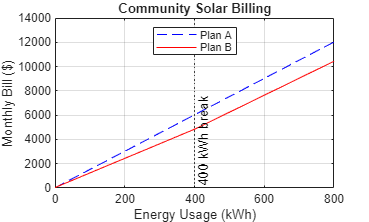

% Task 2: 

plot(x, PA, 'LineWidth', 0.5, 'LineStyle','--','Color','blue'); hold on;
plot(x, PB, 'LineWidth', 0.5, 'Color','red' );


 xline(400,':k','Label','400 kWh break','Color','black','LabelVerticalAlignment','bottom')


xlabel('Energy Usage (kWh)');
ylabel('Monthly Bill ($)');
title('Community Solar Billing');
legend('Plan A', 'Plan B', 'Location','north'); grid on;

CreateDataPairs (x, PA);

x =      0    25    50    75   100   125   150   175   200   225   250   275   300   325   350   375   400   425   450   475   500   525   550   575   600   625   650   675   700   725   750   775   800


PA =           25         400         775        1150        1525        1900        2275        2650        3025        3400        3775        4150        4525        4900        5275        5650        6025        6400        6775        7150        7525        7900        8275        8650        9025        9400        9775       10150       10525       10900       11275       11650       12025



function CreateDataPairs (x, PA)

x
PA

end



% A&B intersection

intersec1 = (40-25)/(15-12); % x=5
intersec2 = -785/5; %invalid

fprintf('Plan A & B have the same cost at x=%.2f kWh (only valid solution).\n',intersec1);

Plan A & B have the same cost at x=5.00 kWh (only valid solution).


%table atleast 10 rows

UsageV = (0:40:800);
PAV = 15*UsageV + 25;

PBV = zeros(size(UsageV));
PBV(UsageV <= 400) = 12 * UsageV(UsageV <= 400) + 40;
PBV(UsageV > 400) = 14 * UsageV(UsageV > 400) + (40 - 2 * 400);
BillTab
labels = {'Usage(kWh)','Plan A Bill','Plan B Bill'};
validNames = matlab.lang.makeValidName(labels);
BillTab = table(UsageV, PAV, PBV, 'VariableNames', validNames);


% reccommendation
fprintf(['RECCOMMENDATIONS\n'])

RECCOMMENDATIONS


fprintf(['- for low energy usage (about 0-5 kWh), Plan B is the cheaper option.\n'])

- for low energy usage (about 0-5 kWh), Plan B is the cheaper option.


fprintf(['- for energy usage above 5 kWh, Plan A is the best option, that includes at and above 400 kwh.\n'])

- for energy usage above 5 kWh, Plan A is the best option, that includes at and above 400 kwh.
